% Presetting
PosExtract=[0; 0; 0; 1];

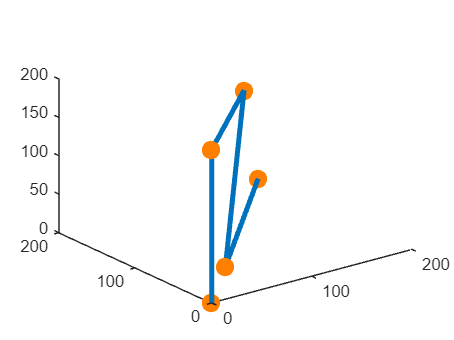

% 4-DoF Manipulator Type 2 Inverse Kinematics test by plot graph
EndpointPos = [200;200;0];

% Inverse Kinematics Solving
x = EndpointPos(1);
y = EndpointPos(2);
z = EndpointPos(3);
L1=200;
L2=200;
L3=200;
L4=200;
phi = 0;
xn = sqrt(x^2 + y^2);
yn = z - L1;
xnn = xn - L4*cos(phi);
ynn = yn - L4*sin(phi);
theta1 = atan2(y, x);
theta3 = -acos((xnn^2+ynn^2-L2^2-L3^2)/(2*L2*L3));
theta2 = atan2(ynn, xnn) - atan2(L3*sin(theta3), L2+L3*cos(theta3));
theta4 = phi - (theta2 + theta3);

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = L1;
T01 = DHParameter(a0, alpha0, d1, theta1);

% Arm1 to Arm2
a1 = 0;
alpha1 = pi/2;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2);

% Arm2 to Arm3
a2 = L2;
alpha2 = 0;
d3 = 0;
T23 = DHParameter(a2, alpha2, d3, theta3);

% Arm3 to Endpoint
a3 = L3;
alpha3 = 0;
d4 = 0;
T34 = DHParameter(a3, alpha3, d4, theta4);

% Arm3 to Endpoint
a4 = L4;
alpha4 = 0;
d5 = 0;
theta5 = 0;
T4E = DHParameter(a4, alpha4, d5, theta5);

% Base to Each Coordinate
T02 = T01*T12;
T03 = T01*T12*T23;
T04 = T01*T12*T23*T34;
T0E = T01*T12*T23*T34*T4E;

% Position of Each Coordinate according to Base Coordinate
p01=T01*PosExtract;
p02=T02*PosExtract;
p03=T03*PosExtract;
p04=T04*PosExtract;
p0E=T0E*PosExtract;

% plot
p = plot3([PosExtract(1,1), p02(1,1), p03(1,1), p04(1,1), p0E(1,1)], [PosExtract(2,1), p02(2,1), p03(2,1), p04(2,1), p0E(2,1)], [PosExtract(3,1), p02(3,1), p03(3,1), p04(3,1), p0E(3,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0];